# URBACH TAILS (Find URBACH energy )

This model will let us quantify if the semiconductor is cristaline or amorphus material. The ubach energy is below the bangap energy governed by the structural disorder or imperfection at the surface. 

## Import Data

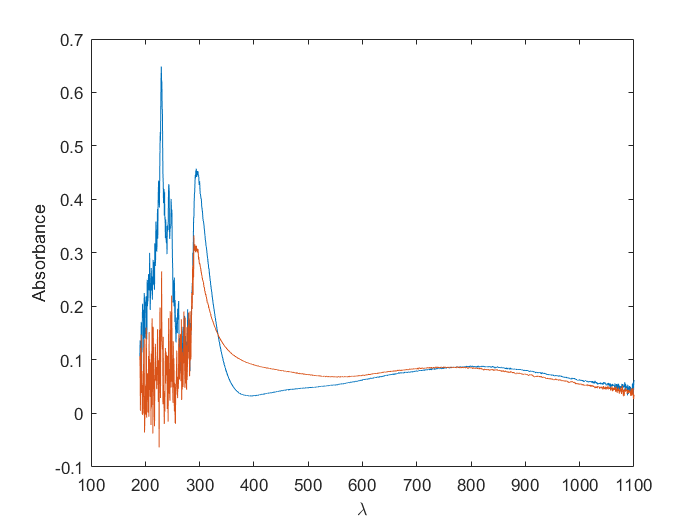

clc; clear ; clf
C_Data = readmatrix("Absorbancia.xlsx - Control.csv"); %[Wavelen | Abs%]
Temp_Data = readmatrix("Absorbancia.xlsx - Tratada250°C.csv"); %[Wavelen | Abs%]
plot(C_Data(:,1),C_Data(:,2),Temp_Data(:,1),Temp_Data(:,2))
xlabel("\lambda")
ylabel("Absorbance")

## Define General Parameters

c = 3 * 10^8;          %Speed of light [m/s]
h = 6.626 *10^(-34);   %Plancks Constant [SI units]
 
n = 2;   %Continous excitation

%Filter non relevant wavelengths (UV-VIS)
kk = find(C_Data(:,1)<300);
jj = find(C_Data(:,1)>750);
index = kk(end)+1:1:jj(1)-1; 

%Define wavelengths and absorbptions
lambda = C_Data(index,1).* 10^-9;
Abs1 = C_Data(index,2);     %Control
Abs2 = Temp_Data(index,2);  %Temperature treatment

% System Parameters
V = c./lambda;      %Frequency 
E = h.*V;           %Energy


## URBACH MODEL

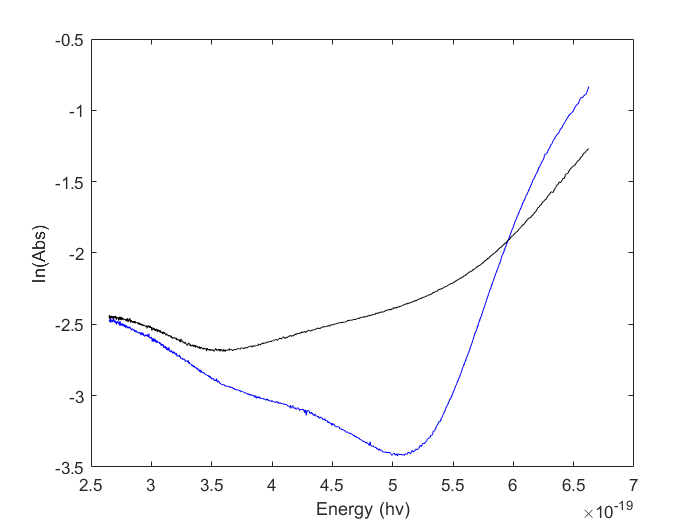

% Y axis
Y1 =  log(Abs1);   %Control                                                                                                                                                                                                                                                                                                                               
Y2 =  log(Abs2);   %Temperature treatment

plot(E,Y1,"b",E,Y2,"k")
xlabel("Energy (hv)")
ylabel("ln(Abs)")
hold on

## Simple Linear Regresion

Its important to pinpoint where the line begin to show linearity in order to adjust the linear regresion.  In this case we use an energy of: $E=5\ldotp 5*{10}^{-19} \;$[Joule]

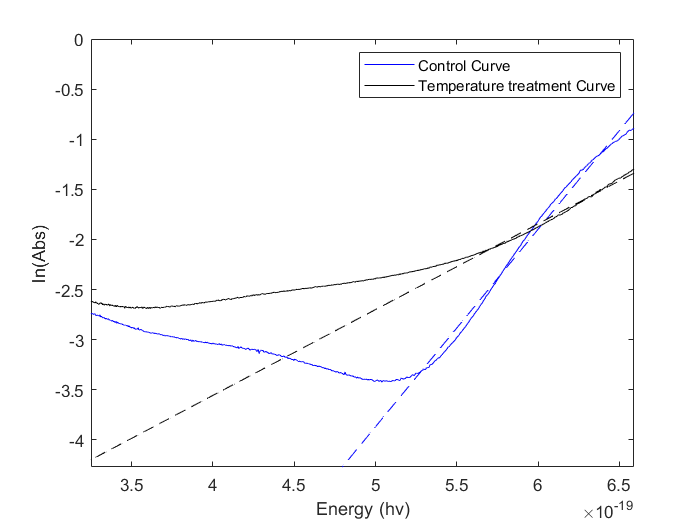

%Define parameters of linear regresion
E_reg = E.*(E>5.5e-19); %Filter E to fit the line
E_reg(~any(E_reg,2), :) = [];
% E_reg = E;

% Y1_reg = linspace(Y1(end),Y1(1),size(E_reg,1));
% Y2_reg = linspace(Y2(end),Y2(1),size(E_reg,1));
Y1_reg = Y1(1:size(E_reg,1), 1);
Y2_reg = Y2(1:size(E_reg,1), 1);

%Calculate the Average
E_ave = mean(E_reg); 

%Control
Y1_ave = mean(Y1_reg);
m1 = sum((E_reg-E_ave).*(Y1_reg-Y1_ave))./sum((E_reg-E_ave).^2);
b1 = Y1_ave - m1.*E_ave;

%Temperature
Y2_ave = mean(Y2_reg);
m2 = sum((E_reg-E_ave).*(Y2_reg-Y2_ave))./sum((E_reg-E_ave).^2);
b2 = Y2_ave - m2.*E_ave;


plot(E, m1.*E +b1,"b--", E,m2.*E +b2,"k--")
xlim([0.000000000000000000325 0.000000000000000000659])
ylim([-4.27 0])
legend("Control Curve", "Temperature treatment Curve")
xlabel("Energy (hv)")
ylabel("ln(Abs)")

fprintf("The Urbach energy of the control material is %2.25f eV ", 1/m1) %~e19

The Urbach energy of the control material is 0.0000000000000000000507730 eV 

fprintf("The Urbach energy of the temperature treated material is %2.25f eV ", 1/m2) %~e18

The Urbach energy of the temperature treated material is 0.0000000000000000001168063 eV 

Means m1 is more cristaline that m2 by one order of magnitude. 